PAR = [Pareto_front, Pareto_Fvals];
[Par2, index] = sortrows(PAR, [5 4 6]);
PAR3 = [index, Par2];
PAR4 = unique(PAR3(:,2:7),'rows');
X1 = PAR4(:,1:3);
Z1 = PAR4(:,4:6);

Lz = size(X1, 1);
Z2 = zeros(size(Z1));

for i = 1:Lz
    [f, g] = minimizeFlx(X1(i,1),X1(i,2),X1(i,3));
    Z2(i,:)= g;
end


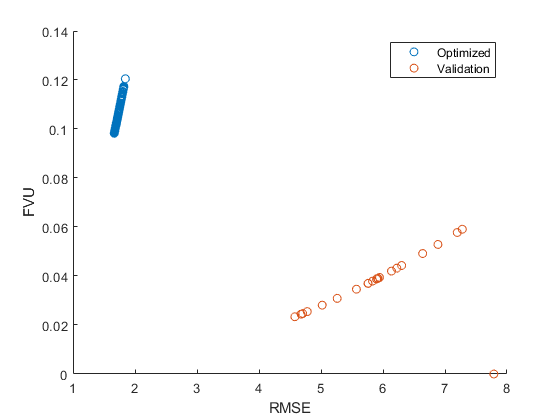

figure
hold on
scatter3(Z1(:,1),Z1(:,2),Z1(:,3),'DisplayName','Optimized')
scatter3(Z2(:,1),Z2(:,2),Z2(:,3),'DisplayName','Validation')
xlabel('RMSE')
ylabel('FVU')
zlabel('Residual')
hold off
lgd = legend;